# **Trayectorias**

Se comienza por establecer los arcos que establecen el rango.

thetaMin = linspace(0,360,100);
rMin = 100;
xRanMin = -rMin*cosd(thetaMin);
yRanMin = rMin*sind(thetaMin);
rMax = 200;
thetaMax = linspace(0,360,100);
xRanMax = -rMax*cosd(thetaMax);
yRanMax = rMax*sind(thetaMax);
N = 3;

## Trayectorias

### Triángulo

xiT = 100;
yiT = -100;
Len = 50;
[xT, yT] = triEq(xiT,yiT,Len,N);

### Círculo

xCC = 100;
yCC = 100;
R = 30;
[xC, yC] = circleDiscrete(xCC,yCC,R,8);

## Letras

s = 20;
xF = 105;
yF = s+10;
[xL, yL] = FINLetter(xF,yF,20,N);

## Líneas Paralelas

Largo = s*3 + 20;
[xP, yP] = Parallel(xF+10+2*s,yF,s,Largo,N);

## Puntos

[xDots, yDots] = Dots(10,110,15,5);

## Gráfica

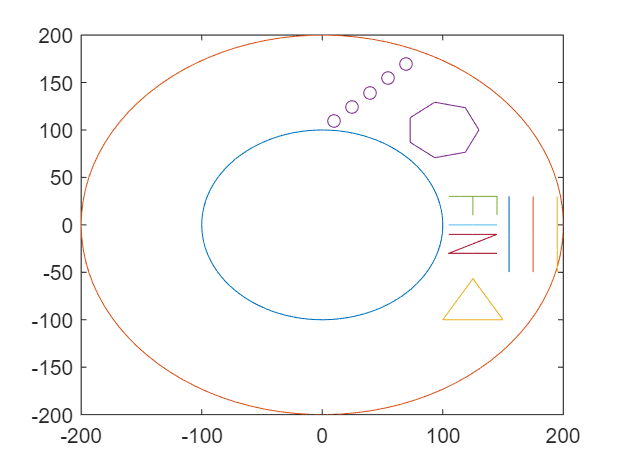

plot(xRanMin,yRanMin)
hold on
plot(xRanMax,yRanMax)
plot(xT,yT)
plot(xC, yC)
plot(xL(1:5*N),yL(1:5*N))
plot(xL(5*N+1:7*N),yL(5*N+1:7*N))
plot(xL(7*N+1:10*N),yL(7*N+1:10*N))
plot(xP(1:N),yP(1:N))
plot(xP(N+1:2*N),yP(N+1:2*N))
plot(xP(2*N+1:3*N),yP(2*N+1:3*N))
plot(xDots,yDots,'o')

## Posiciones articulares

q0 = [0,0,0,0,-0.15]

q0 =          0         0         0         0   -0.1500


q0Op = [0,0,0,0,0.2]

q0Op =          0         0         0         0    0.2000


### **Recolección del marcador**

px = 180;
py = -180;
zp = 120;
qRecoleccion = zeros(6,5);
qRecoleccion(1,:) = q0Op;
param = [[px,py,zp+30,0.2];[px,py,zp,0.2];[px,py,zp,-0.15];[px,py,zp+30,-0.15]];
for i = 1:4
    [q1, q2, q3, q4, q5] = phinv(param(i,1), param(i,2), param(i,3), param(i,4));
    qRecoleccion(i+1,:) = [q1, q2, q3, q4, q5];
end
qRecoleccion(6,:) = q0;

### **Dejado del marcador**

qDejado = (fliplr(qRecoleccion'))';

## Triángulo Equilátero

qTriangle = zeros(length(xT)+4,5);
qTriangle(1,:) = q0;
qTriangle(end,:) = q0;
zT = 120;
for i = 2:length(qTriangle)-1
    if(i==2)
        param = [xT(1), yT(1), zT+50,-0.15];
    elseif(i==(length(qTriangle)-1))
        param = [xT(end), yT(end), zT+50,-0.15];
    else
        param = [xT(i-2), yT(i-2), zT,-0.15];
    end
    [q1, q2, q3, q4, q5] = phinv(param(1,1), param(1,2), param(1,3)+i*5, param(1,4));
    qTriangle(i,:) = [q1, q2, q3, q4, q5];
end
qTriangle;

### Círculo

qCircle = zeros(length(xC)+4,5);
qCircle(1,:) = q0;
qCircle(end,:) = q0;
zC = 120;

for i = 2:length(qCircle)-1
    if(i==2)
        param = [xC(1), yC(1), zC+50,-0.15];
    elseif(i==(length(qCircle)-1))
        param = [xC(end), yC(end), zC+50,-0.15];
    else
        param = [xC(i-2), yC(i-2), zC,-0.15];
    end
    [q1, q2, q3, q4, q5] = phinv(param(1,1), param(1,2), param(1,3)+i*5, param(1,4));
    qCircle(i,:) = [q1, q2, q3, q4, q5];
end
qCircle;

## Letras

qLetter = zeros(length(xL)+8,5);
qLetter(1,:) = q0;
qLetter(end,:) = q0;
zL = 120;
j = 1;
for i = 2:length(qLetter)-1
    if((i==2)||(i==(4+5*N))||(i==(6+7*N)))
        param = [xL(j), yL(j), zL+50,-0.15];
    elseif((i==(3+5*N))||(i==(5+7*N)))
        param = [xL(j-1), yL(j-1), zL+50,-0.15];
    elseif(i==(length(qLetter)-1))
        param = [xL(end), yL(end), zL+50,-0.15];
    else
        param = [xL(j), yL(j), zL,-0.15];
        j = j+1;
    end
    [q1, q2, q3, q4, q5] = phinv(param(1,1), param(1,2), param(1,3), param(1,4));
    qLetter(i,:) = [q1, q2, q3, q4, q5];
end
qLetter;

## Líneas Paralelas

qPar = zeros(length(xP)+8,5);
qPar(1,:) = q0;
qPar(end,:) = q0;
zP = 120;
j = 1;
for i = 2:length(qPar)-1
    if((i==2)||(i==(4+N))||(i==(6+2*N)))
        param = [xP(j), yP(j), zP+50,-0.15];
    elseif((i==(3+N))||(i==(5+2*N)))
        param = [xP(j-1), yP(j-1), zP+50,-0.15];
    elseif(i==(length(qPar)-1))
        param = [xP(end), yP(end), zp+50,-0.15];
    else
        param = [xP(j), yP(j), zP,-0.15];
        j = j+1;
    end
    [q1, q2, q3, q4, q5] = phinv(param(1,1), param(1,2), param(1,3), param(1,4));
    qPar(i,:) = [q1, q2, q3, q4, q5];
end
qPar;

## Puntos

qDots = zeros(3*length(xDots)+2,5);
qDots(1,:) = q0;
qDots(end,:) = q0;
zD = 120;
j = 1;
for i = 1:5
    for j=1:3
        if(j==1)
            param = [xDots(i), yDots(i), zD+50,-0.15];
        elseif(j==2)
            param = [xDots(i), yDots(i), zD,-0.15];
        elseif(j==3)
            param = [xDots(i), yDots(i), zD+50,-0.15];    
        end
        [q1, q2, q3, q4, q5] = phinv(param(1,1), param(1,2), param(1,3), param(1,4));
        qDots((i-1)*3+(j-1)+2,:) = [q1, q2, q3, q4, q5];
    end
end
qDots

qDots =          0         0         0         0   -0.1500
    1.4801   -1.3271    1.1632    0.1639   -0.1500
    1.4801   -1.1752    1.6571   -0.4818   -0.1500
    1.4801   -1.3271    1.1632    0.1639   -0.1500
    1.3734   -1.1000    1.1201   -0.0201   -0.1500
    1.3734   -0.7576    1.5589   -0.8013   -0.1500
    1.3734   -1.1000    1.1201   -0.0201   -0.1500
    1.2925   -0.8726    1.0368   -0.1642   -0.1500
    1.2925   -0.4941    1.4117   -0.9176   -0.1500
    1.2925   -0.8726    1.0368   -0.1642   -0.1500
